# Furuta Pendulum: Open-Loop Stability, Controllability & Observability Analysis

This Live Script analyzes the open-loop linear dynamics of the Furuta Rotary Inverted Pendulum at **both** equilibria — the **upright apex** ($\theta_1 = 0$) and the **hanging downward position** ($\theta_1 = \pi$) — covering five core control-engineering checks before controller synthesis:

- **Eigenvalues:** Open-loop poles $\lambda_i$ and physical mode interpretation.

- **Open-Loop Zeros and Poles:** Non-minimum phase RHP zero check and pole–zero maps.

- **Controllability and Observability:** Kalman rank tests for full-state feedback and encoder sensing.

- **Open-Loop Step Response:** Time-domain arm and pendulum response to $V_a = 1\text{ V}$.

- **Open-Loop Bode Plot:** Magnitude and phase characteristics guiding PID, Pole Placement, and LQR design.

**Symbol Glossary:**

- $\mathbf{x} = [\theta_0,\; \dot{\theta}_0,\; \theta_1,\; \dot{\theta}_1]^T$: State vector (arm angle, arm speed, pendulum angle from upright, pendulum speed).

- $u = V_a$: Armature voltage input [V]; $\mathbf{y} = C\mathbf{x} = [\theta_0,\; \theta_1]^T$: Encoder angle measurements [rad].

- $\lambda_i$: Open-loop eigenvalues (poles) of $A$; $\omega_n = |\lambda_i|$: Natural frequency [rad/s]; $\zeta$: Damping ratio; $\tau = 1/|\mathrm{Re}(\lambda_i)|$: Time constant [s].

- $p_{\text{RHP}},\; z_{\text{RHP}}$: Right-half-plane unstable pole and non-minimum phase zero [rad/s].

- $\mathcal{C} = [B,\; AB,\; A^2B,\; A^3B]$ and $\mathcal{O} = [C;\; CA;\; CA^2;\; CA^3]$: Kalman controllability and observability matrices.

**MATLAB Utilities Used:**

- `eig(A)` computes the open-loop poles directly from the state matrix $A$.

- `tzero(sys)` computes transmission zeros directly from state-space matrices; `minreal()` removes exact pole–zero cancellations at $s = 0$.

- `ctrb(A,B)`, `obsv(A,C)`, and `rank()` perform Kalman's controllability and observability rank proofs.

- `step(sys, t)` simulates the linear unit-voltage ($1\text{ V}$) step response; `bode(sys, w)` computes the exact frequency response $G(j\omega)$.

## 0. Setup & Plant Loading

Load the SSOT parameters from `config/load_parameters.m`, build both linearized models with `config/build_plant.m`, and run `analyze_open_loop_stability(plant, params)`.

ensureProjectPaths();

params = load_parameters();
plant  = build_plant(params);
rep    = analyze_open_loop_stability(plant, params);
st     = stabilityPlotStyle();

fprintf('Loaded plant: L0 = %.4f m, l1 = %.4f m, m1 = %.4f kg, N = %g, Ts = %.1f ms\n', ...
    params.L0, params.l1, params.m1, params.N, params.Ts * 1e3);

Loaded plant: L0 = 0.0475 m, l1 = 0.0572 m, m1 = 0.0458 kg, N = 19, Ts = 2.0 ms


## 1. Eigenvalues (Open-Loop Poles & Stability)

Solving $\det(\lambda I - A) = 0$ via `eig(A)` yields four poles at each equilibrium:

- $\lambda_1 = 0$ **(both equilibria):** Pure integrator from the cyclic arm angle $\theta_0$ (no mechanical spring returns the arm to zero).

- $\lambda_2 \ll 0$ **(both equilibria):** Fast real LHP pole from motor back-EMF and viscous arm damping.

- $\lambda_{3,4}$ **(upright):** Splits into one stable LHP pole and one **unstable RHP topple pole** ($p_{\text{RHP}} > 0$), proving the upright equilibrium is open-loop unstable and requires active feedback faster than $\tau_{\text{topple}} = 1/p_{\text{RHP}}$.

- $\lambda_{3,4}$ **(downward):** Lightly damped complex-conjugate pair in the open LHP corresponding to natural hanging pendulum oscillations.

modalTable = buildModalTable(rep);
disp(modalTable);

    Equilibrium                  Physical_Mode                  Eigenvalue_rad_s     Omega_n_rad_s    Damping_Zeta    Time_Const_s
    ___________    _________________________________________    _________________    _____________    ____________    ____________

    "upright"      "Cyclic Arm Rotation (theta0)"               "0.000"                      0               NaN             NaN  
    "upright"      "Fast Motor-Arm Back-EMF Decay"              "-715.478"              715.48                 1       0.0013977  
    "upright"      "Inverted Pendulum Stable Convergence"       "-10.858"               10.858                 1          0.0921  
    "upright"      "Inverted Pendulum Unstable Topple (RHP)"    "10.773"                10.773                -1        0.092828  
    "down


fprintf('Upright  verdict: %s (topple tau = %.1f ms = %.1f * Ts)\n', ...
    rep.upright.stability_class, rep.upright.topple_time_const_s * 1e3, rep.upright.sample_ratio_tau_to_Ts);

Upright  verdict: Unstable (1 RHP pole) (topple tau = 92.8 ms = 46.4 * Ts)


fprintf('Downward verdict: %s\n', rep.downward.stability_class);

Downward verdict: Marginally Stable (cyclic theta0 + 3 LHP)


## 2. Open-Loop Zeros and Poles (Non-Minimum Phase Check)

Using `tzero()` on both equilibria exposes three distinct zero behaviors:

- **MIMO system** ($V_a \to [\theta_0,\; \theta_1]^T$): `tzero(sys)` is empty because $\theta_0$ and $\theta_1$ share no common blocking zero.

- **Arm channel** ($V_a \to \theta_0$): At the **upright** apex, `tzero(sys(1,1))` reveals a **real RHP (non-minimum phase) zero** at $z_{\text{RHP}} > 0$. Physically, to move the arm to a new angle while balancing, the arm must first swing **backward** (inverse response) to lean the pendulum forward — limiting arm-tracking bandwidth to $\omega_{c,\theta_0} \lesssim z_{\text{RHP}}/2$. At the **downward** position, these become **minimum-phase LHP zeros** (an antiresonance notch).

- **Pendulum channel** ($V_a \to \theta_1$): After removing the cyclic $s = 0$ cancellation via `minreal()`, one **origin zero** ($z = 0$) remains (constant arm speed exerts zero pivot acceleration). The high-frequency input gain flips sign between equilibria: $B_{4,\text{up}} < 0$ (initial negative kick for $V_a > 0$) vs. $B_{4,\text{down}} > 0$.

zeroTable = buildZeroTable(rep);
disp(zeroTable);

    Equilibrium    MIMO_tzero          SISO_Va_to_theta0_Zeros          SISO_Va_to_theta1_Zeros         NMP_in_theta0            Input_Gain_B4    
    ___________    ___________    __________________________________    _______________________    _______________________    ____________________

    "upright"      "None ([])"    "10.704, -10.932"                               "0"              "YES (RHP z = +10.704)"    "Negative (-1064.5)"
    "downward"     "None ([])"    "-0.114 +10.817j, -0.114 -10.817j"              "0"              "NO (Minimum Phase)"       "Positive (+1064.5)"




fprintf('Upright bandwidth trade-off: Stabilization floor 2*p_RHP = %.1f rad/s vs. arm-tracking ceiling z_RHP/2 = %.1f rad/s.\n', ...
    rep.upright.bw_floor_rad_s, rep.upright.bw_ceiling_theta0_rad_s);

Upright bandwidth trade-off: Stabilization floor 2*p_RHP = 21.5 rad/s vs. arm-tracking ceiling z_RHP/2 = 5.4 rad/s.


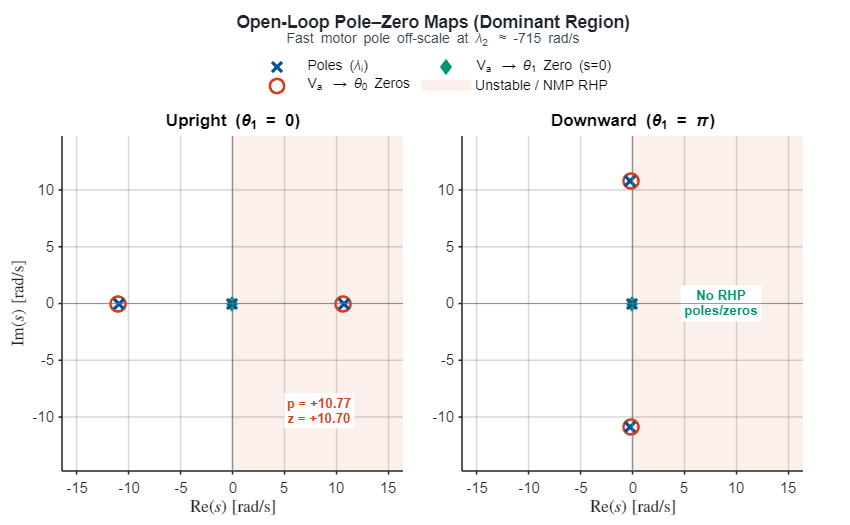


plotPoleZeroComparison(rep, st);

## 3. Controllability and Observability (Kalman Rank Proofs)

A 4th-order system is **completely controllable** if $\mathrm{rank}(\mathcal{C}) = 4$ (meaning motor voltage $V_a$ alone can place all four closed-loop poles) and **completely observable** if $\mathrm{rank}(\mathcal{O}) = 4$ (meaning all four states can be reconstructed from encoder angles without velocity tachometers). Comparing single-encoder subsets also proves why hardware needs the arm encoder: with $\theta_1$ alone, $\mathrm{rank}(\mathcal{O}_{\theta_1}) = 3 < 4$ because the cyclic arm angle $\theta_0$ never affects the pendulum dynamics.

ctrlObsvTable = buildCtrlObsvTable(rep);
disp(ctrlObsvTable);

    Equilibrium    ctrb_Rank    Controllability    obsv_Both_Rank    Observability    obsv_theta0_Only_Rank    obsv_theta1_Only_Rank
    ___________    _________    _______________    ______________    _____________    _____________________    _____________________

    "upright"          4        "Controllable"           4           "Observable"               4                        3          
    "downward"         4        "Controllable"           4           "Observable"               4                        3          



## 4. Open-Loop Step Response ($V_a = 1\text{ V}$)

Calling `step()` on `plant.upright.sys` ($0\text{--}0.30\text{ s}$) and `plant.downward.sys` ($0\text{--}2.0\text{ s}$) confirms the modal and zero analysis directly in the time domain:

- **Upright:** The arm accelerates forward ($\theta_0 > 0$), kicking the pendulum **negative** ($B_4 < 0$) into rapid exponential topple driven by $p_{\text{RHP}}$.

- **Downward:** The arm ramps smoothly (cyclic $\lambda_1 = 0$ integrator), while the pendulum kicks **positive** ($B_4 > 0$) and settles into lightly damped oscillations.

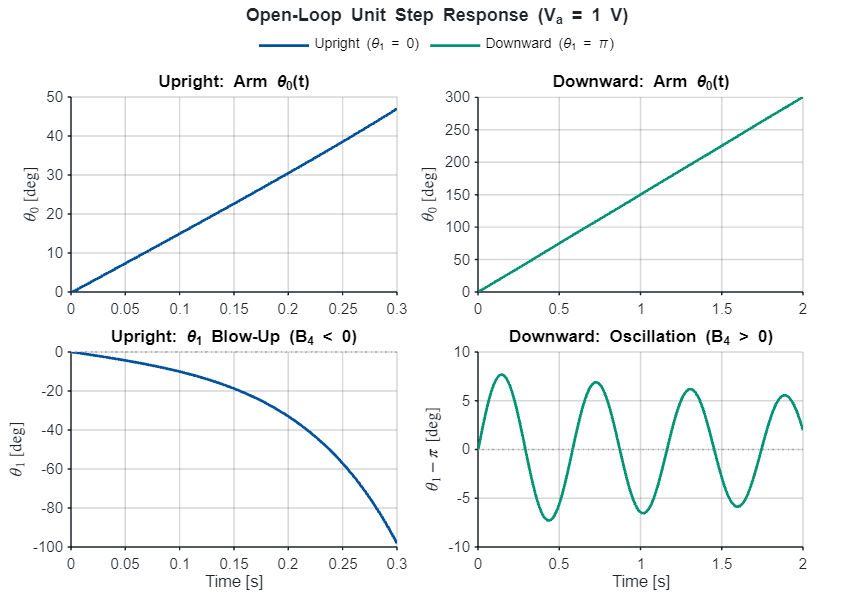

plotStepComparison(plant, st);

## 5. Open-Loop Bode Plot (Frequency Response)

Calling `bode()` on both channels compares how the open-loop poles and zeros shape magnitude and phase across frequency:

- **Arm channel** ($V_a \to \theta_0$): The downward plant shows a sharp antiresonance magnitude dip and phase jump at the pendulum natural frequency, whereas the upright RHP pole and RHP zero nearly cancel in open loop.

- **Pendulum channel** ($V_a \to \theta_1$): Low-frequency $+20\text{ dB/dec}$ roll-off comes from the origin zero ($z = 0$), and the upright phase is shifted by $180^\circ$ relative to downward due to $B_{4,\text{up}} < 0$. The dashed line marks the minimum stabilization bandwidth floor ($2 p_{\text{RHP}}$) for Step 3 controller synthesis.

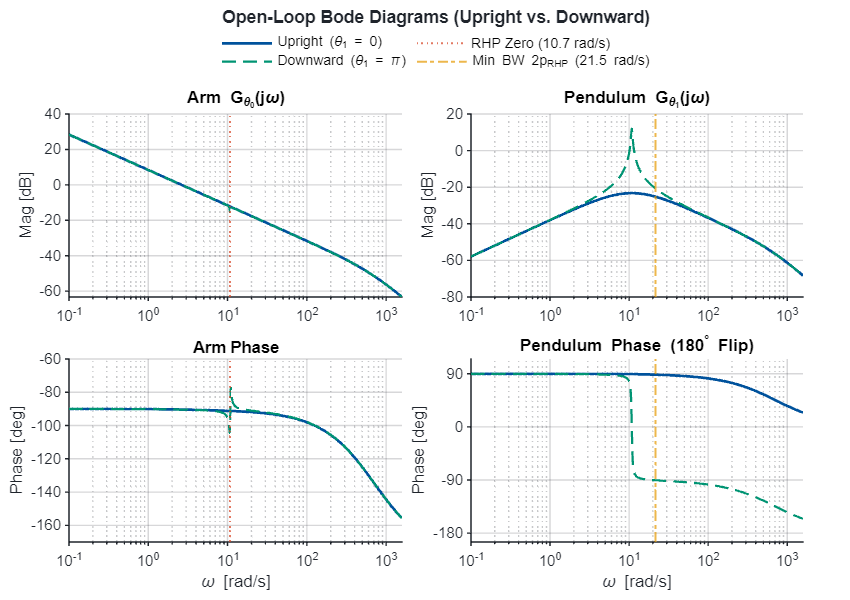

plotBodeComparison(plant, rep, st);

## Local Helper Functions (Tables & Figures)

function tbl = buildModalTable(rep)
    eqs  = {rep.upright, rep.downward};
    Eq   = strings(8, 1);
    Mode = strings(8, 1);
    Pole = strings(8, 1);
    Wn   = zeros(8, 1);
    Zeta = zeros(8, 1);
    Tau  = zeros(8, 1);

    row = 0;
    for e = 1:2
        r = eqs{e};
        for k = 1:4
            row = row + 1;
            Eq(row)   = r.equilibrium;
            Mode(row) = r.mode_labels(k);
            Pole(row) = formatComplex(r.poles(k));
            Wn(row)   = r.natural_freqs(k);
            Zeta(row) = r.damping_ratios(k);
            Tau(row)  = r.time_constants_s(k);
        end
    end

    tbl = table(Eq, Mode, Pole, Wn, Zeta, Tau, ...
        'VariableNames', {'Equilibrium', 'Physical_Mode', 'Eigenvalue_rad_s', ...
        'Omega_n_rad_s', 'Damping_Zeta', 'Time_Const_s'});
end

function tbl = buildZeroTable(rep)
    eqs  = {rep.upright, rep.downward};
    Eq   = strings(2, 1);
    ZMim = strings(2, 1);
    ZTh0 = strings(2, 1);
    ZTh1 = strings(2, 1);
    NMP  = strings(2, 1);
    B4s  = strings(2, 1);

    for e = 1:2
        r = eqs{e};
        Eq(e)   = r.equilibrium;
        ZMim(e) = formatComplexList(r.zeros_mimo);
        ZTh0(e) = formatComplexList(r.zeros_theta0);
        ZTh1(e) = formatComplexList(r.zeros_theta1);
        if r.is_nmp_theta0
            NMP(e) = sprintf('YES (RHP z = +%.3f)', r.rhp_zero_theta0);
        else
            NMP(e) = "NO (Minimum Phase)";
        end
        if r.b4_sign < 0
            B4s(e) = sprintf('Negative (%.1f)', r.b4_gain);
        else
            B4s(e) = sprintf('Positive (+%.1f)', r.b4_gain);
        end
    end

    tbl = table(Eq, ZMim, ZTh0, ZTh1, NMP, B4s, ...
        'VariableNames', {'Equilibrium', 'MIMO_tzero', 'SISO_Va_to_theta0_Zeros', ...
        'SISO_Va_to_theta1_Zeros', 'NMP_in_theta0', 'Input_Gain_B4'});
end

function tbl = buildCtrlObsvTable(rep)
    eqs    = {rep.upright, rep.downward};
    Eq     = strings(2, 1);
    CRank  = zeros(2, 1);
    CStat  = strings(2, 1);
    ORank  = zeros(2, 1);
    OStat  = strings(2, 1);
    ORank0 = zeros(2, 1);
    ORank1 = zeros(2, 1);

    for e = 1:2
        r = eqs{e};
        Eq(e)     = r.equilibrium;
        CRank(e)  = r.ctrb.rank;
        CStat(e)  = passLabel(r.ctrb.is_controllable, "Controllable", "Uncontrollable");
        ORank(e)  = r.obsv.rank;
        OStat(e)  = passLabel(r.obsv.is_observable, "Observable", "Unobservable");
        ORank0(e) = r.obsv.rank_theta0_only;
        ORank1(e) = r.obsv.rank_theta1_only;
    end

    tbl = table(Eq, CRank, CStat, ORank, OStat, ORank0, ORank1, ...
        'VariableNames', {'Equilibrium', 'ctrb_Rank', 'Controllability', ...
        'obsv_Both_Rank', 'Observability', 'obsv_theta0_Only_Rank', 'obsv_theta1_Only_Rank'});
end

function plotPoleZeroComparison(rep, st)
    fig = newStyledFigure('Figure 1: Open-Loop Pole-Zero Maps', [100, 100, 680, 420]);
    tl  = tiledlayout(fig, 1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    title(tl, 'Open-Loop Pole–Zero Maps (Dominant Region)', ...
        'FontSize', st.superTitleFont, 'FontWeight', 'bold', 'Color', st.textColor);
    subtitle(tl, sprintf('Fast motor pole off-scale at \\lambda_2 \\approx %.0f rad/s', real(rep.upright.poles(2))), ...
        'FontSize', st.axisFont - 0.5, 'Color', st.slate);

    domScale = max([abs(rep.upright.poles([1, 3, 4])); abs(rep.downward.poles([1, 3, 4])); ...
        abs(rep.upright.zeros_theta0); abs(rep.downward.zeros_theta0)]);
    xLimDom  = [-1.50 * domScale, 1.50 * domScale];
    yLimDom  = [-1.35 * domScale, 1.35 * domScale];

    axL = nexttile(tl, 1);
    [hP, hZ0, hZ1, hRhp] = drawPoleZeroPanel(axL, rep.upright, xLimDom, yLimDom, ...
        'Upright (\theta_1 = 0)', true, st);

    axR = nexttile(tl, 2);
    drawPoleZeroPanel(axR, rep.downward, xLimDom, yLimDom, ...
        'Downward (\theta_1 = \pi)', false, st);

    attachSharedLegend([hP, hZ0, hZ1, hRhp], ...
        {'Poles (\lambda_i)', 'V_a \rightarrow \theta_0 Zeros', ...
         'V_a \rightarrow \theta_1 Zero (s=0)', 'Unstable / NMP RHP'}, 2, st);
end

function [hP, hZ0, hZ1, hRhp] = drawPoleZeroPanel(ax, eqRep, xLimDom, yLimDom, titleStr, showYLabel, st)
    hRhp = patch(ax, [0, xLimDom(2), xLimDom(2), 0], [yLimDom(1), yLimDom(1), yLimDom(2), yLimDom(2)], ...
        st.lin, 'FaceAlpha', 0.08, 'EdgeColor', 'none'); hold(ax, 'on');
    xline(ax, 0, '-', 'Color', [0.45, 0.45, 0.45], 'LineWidth', 0.9);
    yline(ax, 0, '-', 'Color', [0.45, 0.45, 0.45], 'LineWidth', 0.7);

    domPoles = eqRep.poles([1, 3, 4]);
    hZ0 = plot(ax, real(eqRep.zeros_theta0), imag(eqRep.zeros_theta0), 'o', ...
        'Color', st.lin, 'LineWidth', 1.6, 'MarkerSize', 9.0, 'MarkerFaceColor', 'none');
    hZ1 = plot(ax, real(eqRep.zeros_theta1), imag(eqRep.zeros_theta1), 'd', ...
        'Color', st.teal, 'LineWidth', 1.2, 'MarkerSize', 5.5, 'MarkerFaceColor', st.teal);
    hP  = plot(ax, real(domPoles), imag(domPoles), 'x', 'Color', st.nl, 'LineWidth', 2.0, 'MarkerSize', 8.5);

    if eqRep.is_nmp_theta0
        text(ax, eqRep.rhp_zero_theta0 * 0.78, -0.32 * diff(yLimDom), ...
            sprintf('p = +%.2f\nz = +%.2f', eqRep.rhp_pole, eqRep.rhp_zero_theta0), ...
            'HorizontalAlignment', 'center', 'FontSize', 8.0, 'FontWeight', 'bold', ...
            'Color', st.lin, 'BackgroundColor', 'w', 'Margin', 1.5, 'Clipping', 'on');
    else
        text(ax, 0.52 * xLimDom(2), 0, ...
            {'No RHP', 'poles/zeros'}, 'HorizontalAlignment', 'center', ...
            'VerticalAlignment', 'middle', 'FontSize', 8.0, 'FontWeight', 'bold', ...
            'Color', st.teal, 'BackgroundColor', 'w', 'Margin', 2.0, 'Clipping', 'on');
    end

    xlim(ax, xLimDom); ylim(ax, yLimDom);
    xlabel(ax, '$\mathrm{Re}(s)\;[\mathrm{rad/s}]$', 'Interpreter', 'latex');
    if showYLabel
        ylabel(ax, '$\mathrm{Im}(s)\;[\mathrm{rad/s}]$', 'Interpreter', 'latex');
    end
    title(ax, titleStr, 'FontSize', st.titleFont);
    styleAxes(ax, st);
end

function plotStepComparison(plant, st)
    tUp = linspace(0, 0.30, 301).';
    tDn = linspace(0, 2.00, 501).';
    yUp = step(plant.upright.sys,  tUp);
    yDn = step(plant.downward.sys, tDn);

    fig = newStyledFigure('Figure 2: Open-Loop Step Response (1 V)', [100, 100, 680, 480]);
    tl  = tiledlayout(fig, 2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    title(tl, 'Open-Loop Unit Step Response (V_a = 1 V)', ...
        'FontSize', st.superTitleFont, 'FontWeight', 'bold', 'Color', st.textColor);

    ax11 = nexttile(tl, 1);
    hUp = plot(ax11, tUp, rad2deg(yUp(:, 1)), '-', 'Color', st.nl, 'LineWidth', st.lwMain);
    ylabel(ax11, '$\theta_0\;[\mathrm{deg}]$', 'Interpreter', 'latex');
    title(ax11, 'Upright: Arm \theta_0(t)', 'FontSize', st.titleFont);
    styleAxes(ax11, st);

    ax12 = nexttile(tl, 2);
    hDn = plot(ax12, tDn, rad2deg(yDn(:, 1)), '-', 'Color', st.teal, 'LineWidth', st.lwMain);
    ylabel(ax12, '$\theta_0\;[\mathrm{deg}]$', 'Interpreter', 'latex');
    title(ax12, 'Downward: Arm \theta_0(t)', 'FontSize', st.titleFont);
    styleAxes(ax12, st);

    ax21 = nexttile(tl, 3);
    plot(ax21, tUp, rad2deg(yUp(:, 2)), '-', 'Color', st.nl, 'LineWidth', st.lwMain); hold(ax21, 'on');
    yline(ax21, 0, ':', 'Color', [0.55, 0.55, 0.55], 'LineWidth', 0.8);
    xlabel(ax21, 'Time [s]');
    ylabel(ax21, '$\theta_1\;[\mathrm{deg}]$', 'Interpreter', 'latex');
    title(ax21, 'Upright: \theta_1 Blow-Up (B_4 < 0)', 'FontSize', st.titleFont);
    styleAxes(ax21, st);

    ax22 = nexttile(tl, 4);
    plot(ax22, tDn, rad2deg(yDn(:, 2)), '-', 'Color', st.teal, 'LineWidth', st.lwMain); hold(ax22, 'on');
    yline(ax22, 0, ':', 'Color', [0.55, 0.55, 0.55], 'LineWidth', 0.8);
    xlabel(ax22, 'Time [s]');
    ylabel(ax22, '$\theta_1 - \pi\;[\mathrm{deg}]$', 'Interpreter', 'latex');
    title(ax22, 'Downward: Oscillation (B_4 > 0)', 'FontSize', st.titleFont);
    styleAxes(ax22, st);

    attachSharedLegend([hUp, hDn], {'Upright (\theta_1 = 0)', 'Downward (\theta_1 = \pi)'}, 2, st);
end

function plotBodeComparison(plant, rep, st)
    wGrid = logspace(-1, 3.2, 600).';
    [mag0_up, ph0_up] = evalBodeDeg(plant.upright.sys(1, 1),  wGrid);
    [mag0_dn, ph0_dn] = evalBodeDeg(plant.downward.sys(1, 1), wGrid);
    [mag1_up, ph1_up] = evalBodeDeg(plant.upright.sys(2, 1),  wGrid);
    [mag1_dn, ph1_dn] = evalBodeDeg(plant.downward.sys(2, 1), wGrid);

    fig = newStyledFigure('Figure 3: Open-Loop Bode Diagrams', [100, 100, 680, 480]);
    tl  = tiledlayout(fig, 2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    title(tl, 'Open-Loop Bode Diagrams (Upright vs. Downward)', ...
        'FontSize', st.superTitleFont, 'FontWeight', 'bold', 'Color', st.textColor);

    bodeTicks = [1e-1, 1e0, 1e1, 1e2, 1e3];

    ax31 = nexttile(tl, 1);
    hBUp = semilogx(ax31, wGrid, mag0_up, '-',  'Color', st.nl,   'LineWidth', st.lwMain); hold(ax31, 'on');
    hBDn = semilogx(ax31, wGrid, mag0_dn, '--', 'Color', st.teal, 'LineWidth', st.lwSec);
    hZln = xline(ax31, rep.upright.rhp_zero_theta0, ':', 'Color', st.lin, 'LineWidth', 1.2);
    ylabel(ax31, 'Mag [dB]');
    title(ax31, 'Arm G_{\theta_0}(j\omega)', 'FontSize', st.titleFont);
    styleAxes(ax31, st); xlim(ax31, [wGrid(1), wGrid(end)]); xticks(ax31, bodeTicks);

    ax32 = nexttile(tl, 2);
    semilogx(ax32, wGrid, mag1_up, '-',  'Color', st.nl,   'LineWidth', st.lwMain); hold(ax32, 'on');
    semilogx(ax32, wGrid, mag1_dn, '--', 'Color', st.teal, 'LineWidth', st.lwSec);
    hPln = xline(ax32, rep.upright.bw_floor_rad_s, '-.', 'Color', st.amber, 'LineWidth', 1.2);
    ylabel(ax32, 'Mag [dB]');
    title(ax32, 'Pendulum G_{\theta_1}(j\omega)', 'FontSize', st.titleFont);
    styleAxes(ax32, st); xlim(ax32, [wGrid(1), wGrid(end)]); xticks(ax32, bodeTicks);

    ax33 = nexttile(tl, 3);
    semilogx(ax33, wGrid, ph0_up, '-',  'Color', st.nl,   'LineWidth', st.lwMain); hold(ax33, 'on');
    semilogx(ax33, wGrid, ph0_dn, '--', 'Color', st.teal, 'LineWidth', st.lwSec);
    xline(ax33, rep.upright.rhp_zero_theta0, ':', 'Color', st.lin, 'LineWidth', 1.2);
    xlabel(ax33, '\omega [rad/s]');
    ylabel(ax33, 'Phase [deg]');
    title(ax33, 'Arm Phase', 'FontSize', st.titleFont);
    styleAxes(ax33, st); xlim(ax33, [wGrid(1), wGrid(end)]); xticks(ax33, bodeTicks);
    ylim(ax33, [-170, -60]);

    ax34 = nexttile(tl, 4);
    semilogx(ax34, wGrid, ph1_up, '-',  'Color', st.nl,   'LineWidth', st.lwMain); hold(ax34, 'on');
    semilogx(ax34, wGrid, ph1_dn, '--', 'Color', st.teal, 'LineWidth', st.lwSec);
    xline(ax34, rep.upright.bw_floor_rad_s, '-.', 'Color', st.amber, 'LineWidth', 1.2);
    xlabel(ax34, '\omega [rad/s]');
    ylabel(ax34, 'Phase [deg]');
    title(ax34, 'Pendulum Phase (180^\circ Flip)', 'FontSize', st.titleFont);
    styleAxes(ax34, st); xlim(ax34, [wGrid(1), wGrid(end)]); xticks(ax34, bodeTicks);
    ylim(ax34, [-195, 115]); yticks(ax34, [-180, -90, 0, 90]);

    attachSharedLegend([hBUp, hBDn, hZln, hPln], ...
        {'Upright (\theta_1 = 0)', 'Downward (\theta_1 = \pi)', ...
         sprintf('RHP Zero (%.1f rad/s)', rep.upright.rhp_zero_theta0), ...
         sprintf('Min BW 2p_{RHP} (%.1f rad/s)', rep.upright.bw_floor_rad_s)}, 2, st);
end

function [magDb, phaseDeg] = evalBodeDeg(sysSiso, wGrid)
    [mag, phase] = bode(sysSiso, wGrid);
    magDb    = 20 * log10(max(squeeze(mag), 1e-16));
    phaseDeg = squeeze(phase);
end

function st = stabilityPlotStyle()
    st = struct();
    st.nl             = [0.00, 0.32, 0.61];  % Deep navy (Upright / Poles)
    st.lin            = [0.84, 0.25, 0.12];  % Vermilion (RHP / NMP Zero)
    st.teal           = [0.00, 0.58, 0.45];  % Teal (Downward / Origin Zero)
    st.amber          = [0.90, 0.60, 0.00];  % Warm amber (BW Floor)
    st.slate          = [0.22, 0.26, 0.31];  % Dark slate (Annotations)
    st.textColor      = [0.12, 0.14, 0.17];
    st.lwMain         = 1.65;
    st.lwSec          = 1.35;
    st.axisFont       = 9.0;
    st.titleFont      = 9.5;
    st.superTitleFont = 10.5;
end

function fig = newStyledFigure(figName, pos)
    fig = figure('Name', figName, 'Color', 'w', 'Position', pos);
end

function styleAxes(ax, st)
    box(ax, 'off');
    grid(ax, 'on');
    ax.GridAlpha  = 0.18;
    ax.FontSize   = st.axisFont;
    ax.LineWidth  = 0.85;
    ax.TickDir    = 'out';
    ax.XColor     = st.textColor;
    ax.YColor     = st.textColor;
end

function attachSharedLegend(handles, labels, nCols, st)
    lgd = legend(handles, labels, 'NumColumns', nCols, ...
        'Box', 'off', 'FontSize', st.axisFont - 0.5);
    lgd.Layout.Tile = 'north';
end

function s = passLabel(tf, yesStr, noStr)
    if tf
        s = string(yesStr);
    else
        s = string(noStr);
    end
end

function s = formatComplex(z)
    if abs(imag(z)) < 1e-6
        s = sprintf('%.3f', real(z));
    else
        s = sprintf('%.3f %+.3fj', real(z), imag(z));
    end
end

function s = formatComplexList(v)
    if isempty(v)
        s = "None ([])";
        return;
    end
    parts = strings(numel(v), 1);
    for k = 1:numel(v)
        if abs(v(k)) < 1e-9
            parts(k) = "0";
        else
            parts(k) = formatComplex(v(k));
        end
    end
    s = strjoin(parts, ', ');
end

function ensureProjectPaths()
    if exist('load_parameters', 'file') && exist('build_plant', 'file') ...
            && exist('analyze_open_loop_stability', 'file')
        return;
    end
    cur = pwd;
    for k = 1:6
        if exist(fullfile(cur, 'startup.m'), 'file')
            addpath(fullfile(cur, 'config'));
            addpath(fullfile(cur, 'control', 'evaluation', 'stability'));
            return;
        end
        parent = fileparts(cur);
        if strcmp(parent, cur), break; end
        cur = parent;
    end
    error('Furuta:RepoRootNotFound', 'Could not locate repository root containing startup.m.');
end